clear
close
clc
rng(1)

syms M_c m g l r b_v b_m J_m real
syms x(t) theta(t) x_dot theta_dot x_ddot theta_ddot
syms tau

params = [M_c; m; g; l; r; b_v; b_m; J_m];
values = [0.3; 0.1; 9.82; 0.05; 0.025; 0.01; 3.71*10^-5; 3.75*10^-7];
% values = [5; 1; 9.82*10; 0.3; 0.075; 0.01; 3.71*10^-5; 3.75*10^-7]/10;
% values = [0.3; 0.1; 9.82; 0.05; 0.025; 0; 0; 0];

% Large balancer
% values = 10*[0.3; 0.1; 9.82/10; 0.05; 0.025; 0.01; 3.71*10^-5; 3.75*10^-7];
% values = [5; 1; 9.82; 0.3; 0.075; 0.01; 3.71*10^-5; 3.75*10^-7];
% values = [5; 10; 9.82; 0.3; 0.075; 0; 0; 0];

% Differentiated variables
vars_diff = [diff(x,t,2); diff(x); x; diff(theta,t,2); diff(theta); theta];

% Inverse pendulum mass dynamics
posx_m = l*sin(theta) + x;
accx_m = diff(posx_m, t, 2); % second derivative

% Force required to accelerate the pendulums mass
F_pend = m*accx_m + b_v*diff(x, t);

% The force applied on the "cart" is
% the force generated by the motors
% minus the reaction force from the pendulum mass (x component)
F_mot = tau/r;
eq1 = (M_c + J_m/r^2)*diff(x,t,2) == F_mot - F_pend;

% Considering the load to be a point mass
% and tau is motor reaction torque
eq2 = m*l^2*diff(theta,t,2) == m*g*l*sin(theta) - m*l*diff(x,t,2)*cos(theta) - tau - b_m*diff(x,t)/r;

% Collect terms
eq1 = collect(lhs(eq1) - rhs(eq1), vars_diff);
eq2 = collect(lhs(eq2) - rhs(eq2), vars_diff);

% Express symbolically
syms x theta
vars_sym = [x_ddot; x_dot; x; theta_ddot; theta_dot; theta];
eq1 = subs(eq1, vars_diff, vars_sym);
eq2 = subs(eq2, vars_diff, vars_sym);

% Nonlinear model
[M, rest] = equationsToMatrix([eq1; eq2], [x_ddot; theta_ddot]);
accels = M \ rest;

f = formula([x_dot;
             theta_dot;
             accels(1);
             accels(2)]);

model = subs(f, formula(params), values);
pendulum_dynamics = matlabFunction(model, 'Vars', {x, theta, x_dot, theta_dot, tau});

% Parameter estimation using linearized models
% Use the normal operating point but
% Create models with variation in parameters

op_state = [0; 0; 0; 0];
op_u = 0;
m_op = [0.1; 0.2; 0.3];
l_op = [0.05; 0.1; 0.15];

x_sym = formula([x; theta; x_dot; theta_dot]);
u_sym = tau;
p = [m; l];

A_sym = jacobian(f, x_sym);
B_sym = jacobian(f, u_sym);

A_op = subs(A_sym, [x_sym; u_sym], [op_state; op_u]);
B_op = subs(B_sym, [x_sym; u_sym], [op_state; op_u]);
C = eye(4);
Ts = 0.1;

Qx = [1, 0, 0, 0;
      0, 1, 0, 0;
      0, 0, 1, 0;
      0, 0, 0, 1];
Qu = 1;

A_grid = cell(3,3);
B_grid = cell(3,3);
K_grid = cell(3,3);
A_norms = zeros(3,3);
B_norms = zeros(3,3);

for i = 1:length(m_op)
    for j = 1:length(l_op)
        % M_c m g l r b_v b_m J_m
        values_p = [0.3; m_op(i); 9.82; l_op(j); 0.025; 0.01; 3.71*10^-5; 3.75*10^-7];

        A_p = double(subs(A_op, formula(params), values_p));
        B_p = double(subs(B_op, formula(params), values_p));

        sys = ss(A_p,B_p,C,0);
        dsys = c2d(sys, Ts);
        Ad_p = dsys.A;
        Bd_p = dsys.B;

        [Kd_p, ~, ~] = dlqr(Ad_p, Bd_p, Qx, Qu);
        K_grid{i,j} = Kd_p;

        % disp("m = " + num2str(m_op(i)) + ", l = " + num2str(l_op(j)) + ", A norm = " + norm(Ad_p,2) + ", B norm = " + norm(Bd_p,2))
        % disp(Ad_p)
        % disp(Bd_p)
        % disp(Kd_p)
        % disp(" ")

        A_norms(i,j) = norm(Ad_p, 2); % Frobenius
        B_norms(i,j) = norm(Bd_p, 2); % Euclidian
        
        A_grid{i,j} = Ad_p;
        B_grid{i,j} = Bd_p;

    end
end

A_norms

A_norms =    39.5530   16.3580   10.2820
   54.1181   21.4218   13.2252
   70.9455   26.9465   16.3669


B_norms

B_norms = 1.0e+03 *

    1.2076    0.3308    0.1719
    0.9912    0.2822    0.1512
    0.9625    0.2734    0.1472


K_grid

K_grid = 3×3 cell array
    {[-7.0693e-04 -0.0358 -3.7211e-04 -0.0023]}    {[-0.0025 -0.0621 -0.0036 -0.0061]}    {[-0.0047 -0.0860 -0.0074 -0.0106]}
    {[-8.4620e-04 -0.0589 -7.8651e-04 -0.0034]}    {[-0.0029 -0.0926 -0.0044 -0.0080]}    {[-0.0052 -0.1203 -0.0084 -0.0131]}
    {[-8.6587e-04 -0.0785 -9.1405e-04 -0.0041]}    {[-0.0029 -0.1167 -0.0046 -0.0091]}    {[-0.0054 -0.1464 -0.0087 -0.0145]}


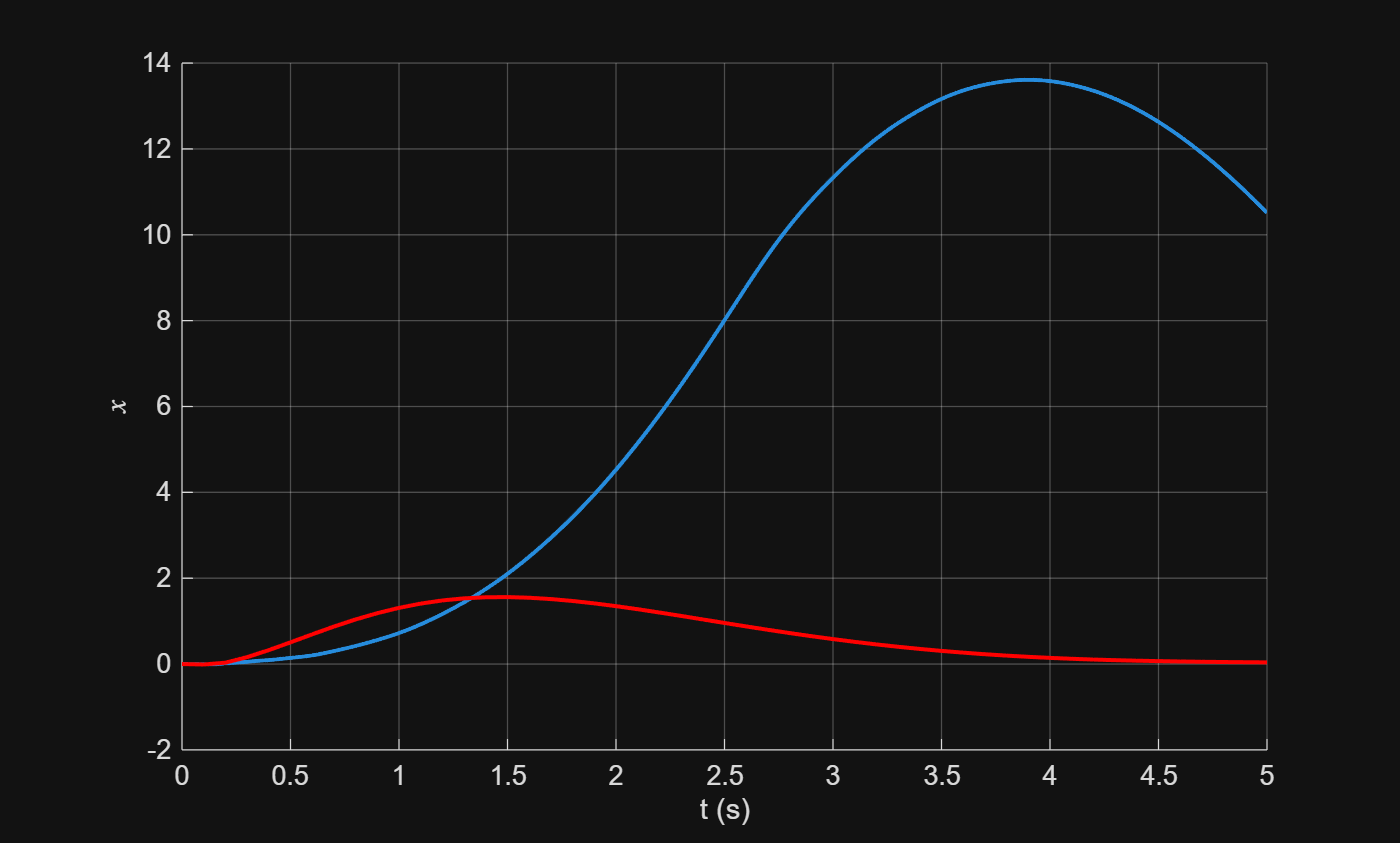

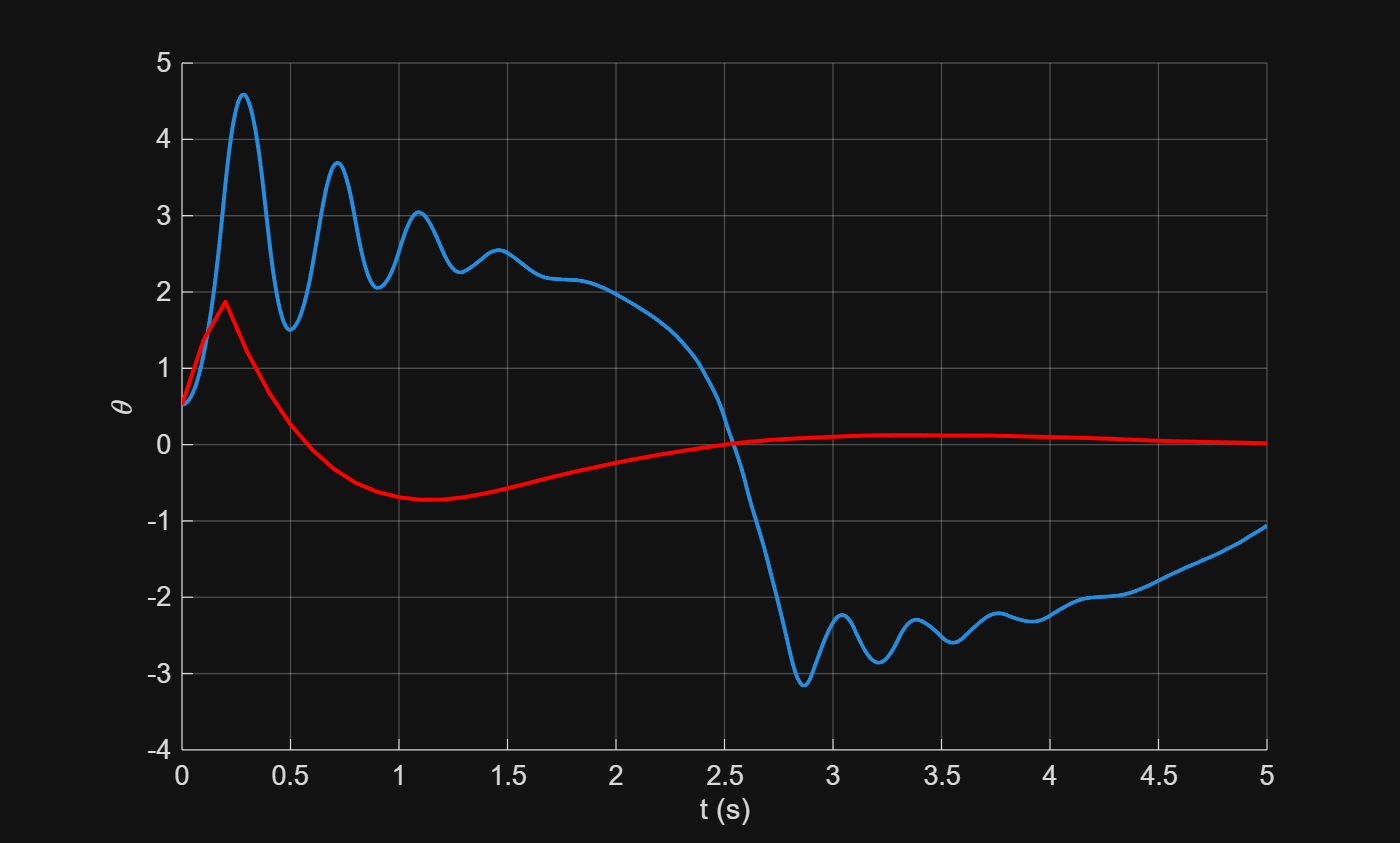

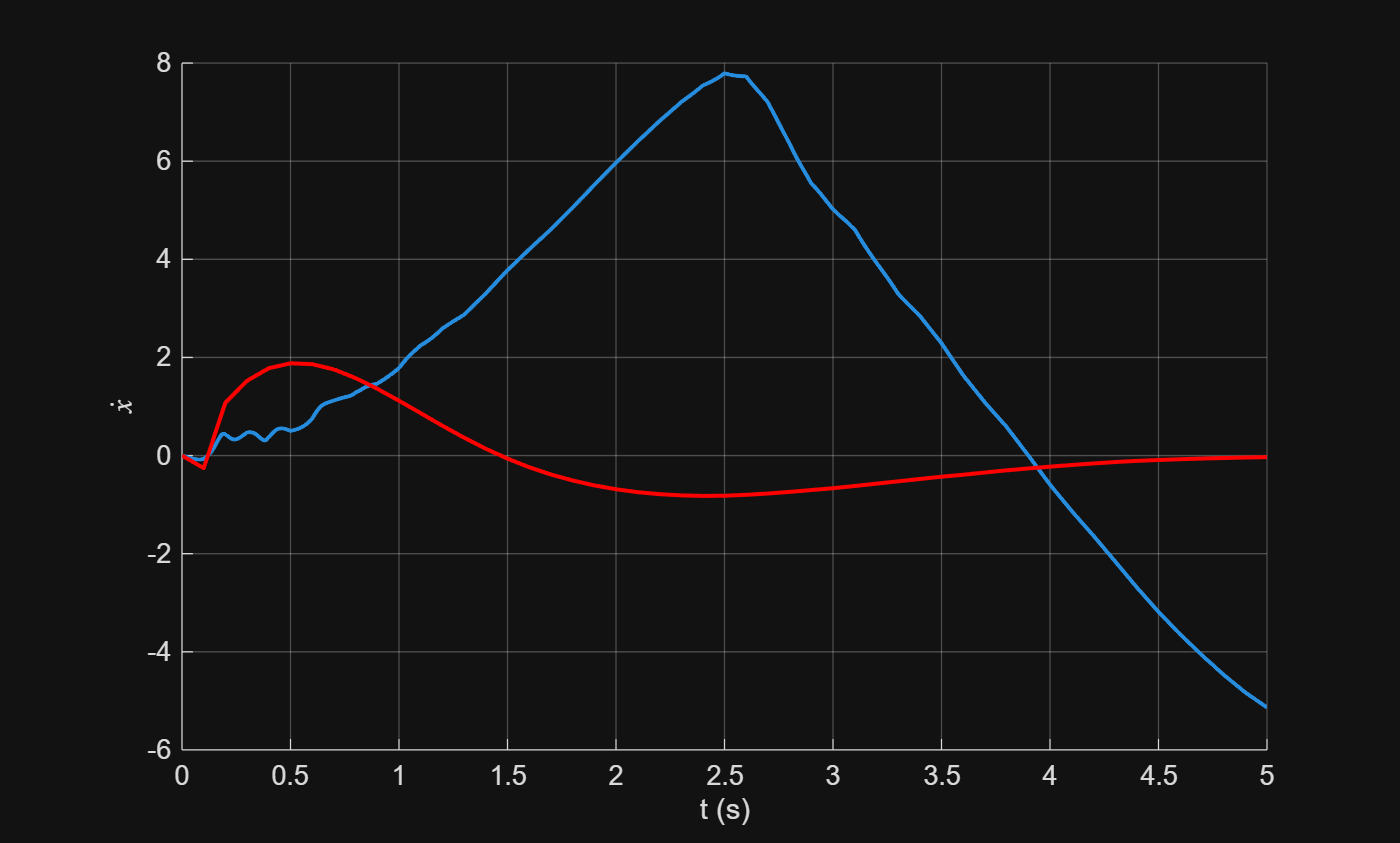

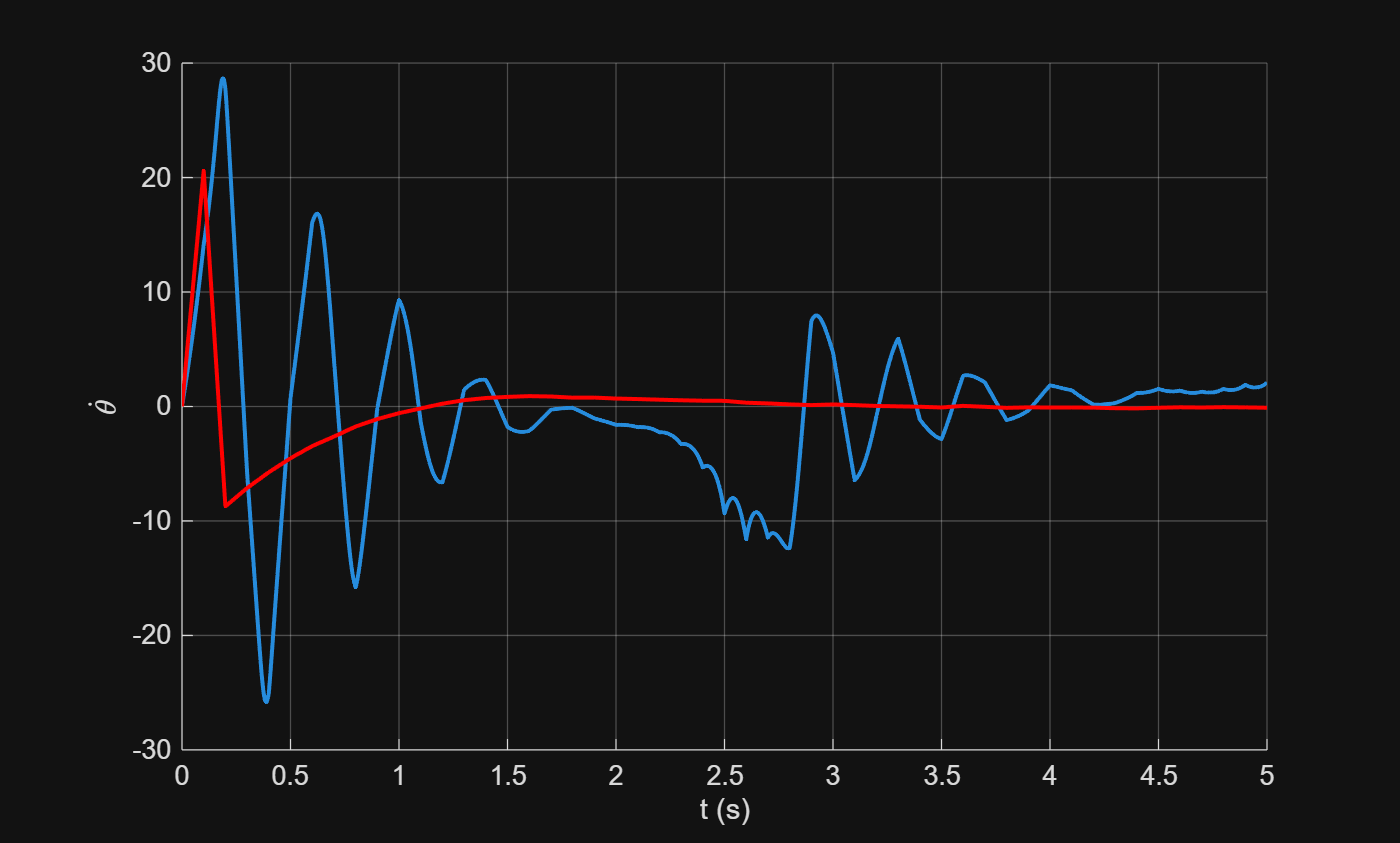


A_nom = A_grid{1,1};
B_nom = B_grid{1,1};

% Simulate nonlinear system
t_end = 5;
T = 0:Ts:t_end;
P0 = 1*eye(4);
x0 = [0; pi/6; 0; 0];

xd = x0;
xd_filtered = x0;
Pd = P0;
ud_prev = 0;

x = x0;
x_filtered = x0;
P = P0;
u_prev = 0;
w_prev = 0;

Q = 0.05*eye(4);
H = eye(4);
R = 0.05*eye(4);
 
% Assume zero mean measurement noise
% rough values:
sigma_x = 0.01*pi/(180*0.025);
sigma_th = 0.05*pi/180;
sigma_x_dot = 0.1*pi/(180*0.025);
sigma_th_dot = 0.05*pi/180;
sigma = [sigma_x; sigma_th; sigma_x_dot;
         sigma_th_dot];

t_traj = [];
t_meas = [];
X = [];
X_filtered = [];
P_filtered = [];
Y = [];
U = [];

Xd = x0.';
Ud = 0;

for k = 1:length(T)-1

    % Compute noise, use in linear and nonlinear model
    n = normrnd(0, sigma);
    
    % Linear simulator (Wrong filter model)
    xd = A_nom*xd + B_nom*ud_prev;
    yd = xd + n;

    [xd_filtered, Pd] = kalmanFilter(yd, H, R, xd_filtered, Pd, A_grid{1,1}, Q, B_grid{1,1}, ud_prev);
    ud = -K_grid{1,1}*xd_filtered;
    ud_prev = ud;
    
    Xd = [Xd; xd.'];
    Ud = [Ud; ud];

    % Nonlinear simulator

    % Integrate nonlinear system over [T(k), T(k+1)] with constant u
    ode = @(t,x) pendulum_dynamics(x(1), x(2), x(3), x(4), u_prev);
    [tk, xk] = ode45(ode, [T(k), T(k+1)], x); % Simulate from "true" state
    x = xk(end,:).';
    y = x + n;
    
    % Estimate matricies and gain
    [A_blend, B_blend, K_blend, w] = gainGridEstimate(y, H, R, x_filtered, P, A_grid, Q, B_grid, u_prev, K_grid, w_prev);
    [x_filtered, P] = kalmanFilter(y, H, R, x_filtered, P, A_blend, Q, B_blend, u_prev);
    u = -K_blend*x_filtered;

    u_prev = u;
    w_prev = w;

    % Append trajectory
    t_traj = [t_traj; tk];
    X = [X; xk];
    
    % Store states
    t_meas = [t_meas; tk(1)];
    Y = [Y; y.'];
    U = [U; u*ones(length(tk),1)];
    X_filtered = [X_filtered; x_filtered.'];
end

%% Plots
states = ["$x$"; "$\theta$"; "$\dot{x}$"; "$\dot{\theta}$"];
for i = 1:size(X,2)
    % Interpolate linear model to nonlinear size
    % for error comparison
    Xd_lerp = interp1(T, Xd(:,i), t_traj);
    figure;
    hold on
    plot(t_traj, X(:,i), 'LineWidth', 1.5);
    plot(T, Xd(:,i), 'LineWidth', 1.5, 'Color', 'r');
    % relative error
    % plot(t_traj, (X(:,i) - Xd_lerp), 'LineWidth', 1.5, 'Color', 'y')
    % scatter(t_meas, Y(:,i), 5, 'filled');
    % plot(t_meas, X_filtered(:,i), 'LineWidth',1.5);

    xlabel('t (s)');
    ylabel(states(i),'Interpreter','latex');
    grid on;
    hold off
end

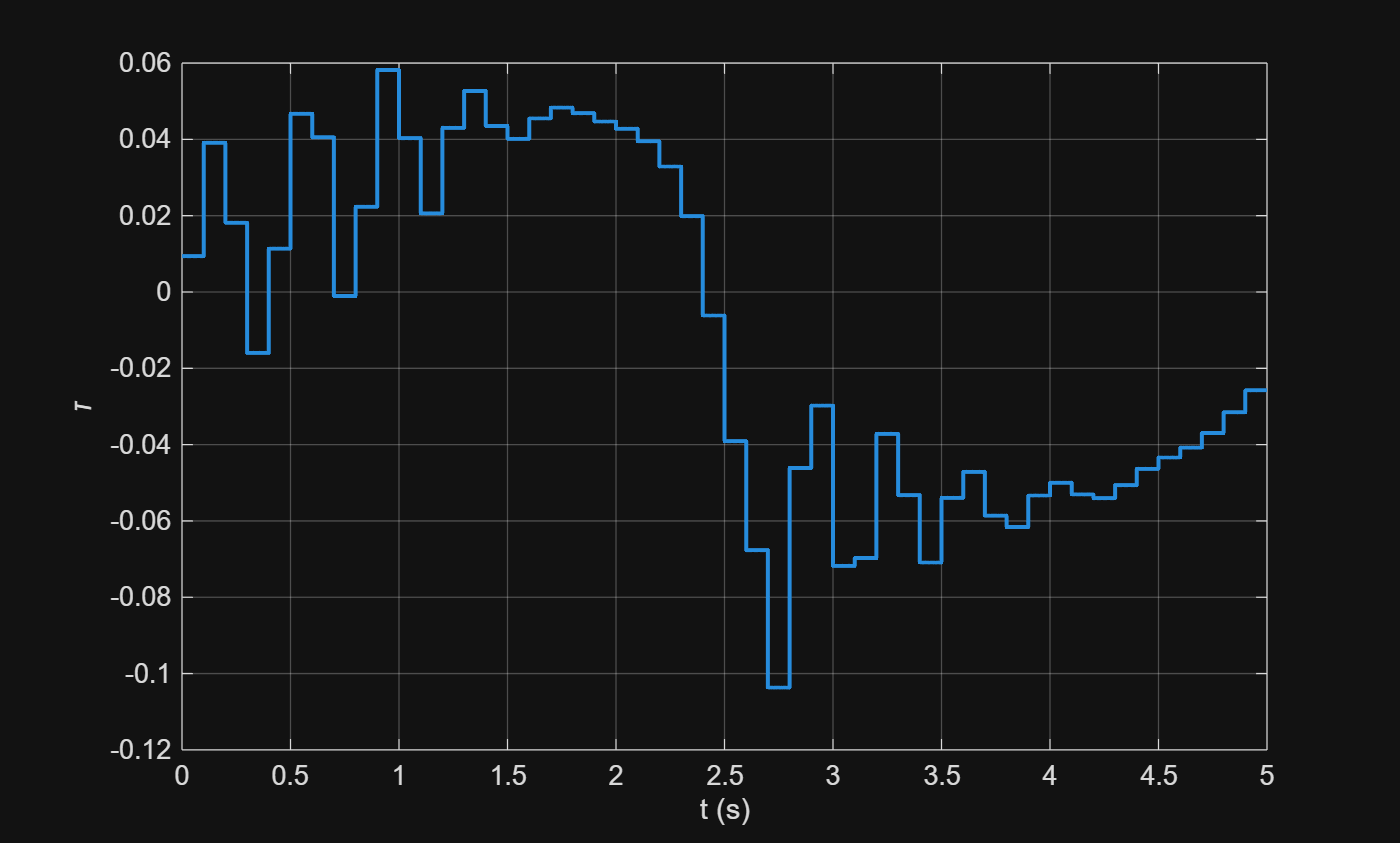


figure(2)
plot(t_traj, U, 'LineWidth', 1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;

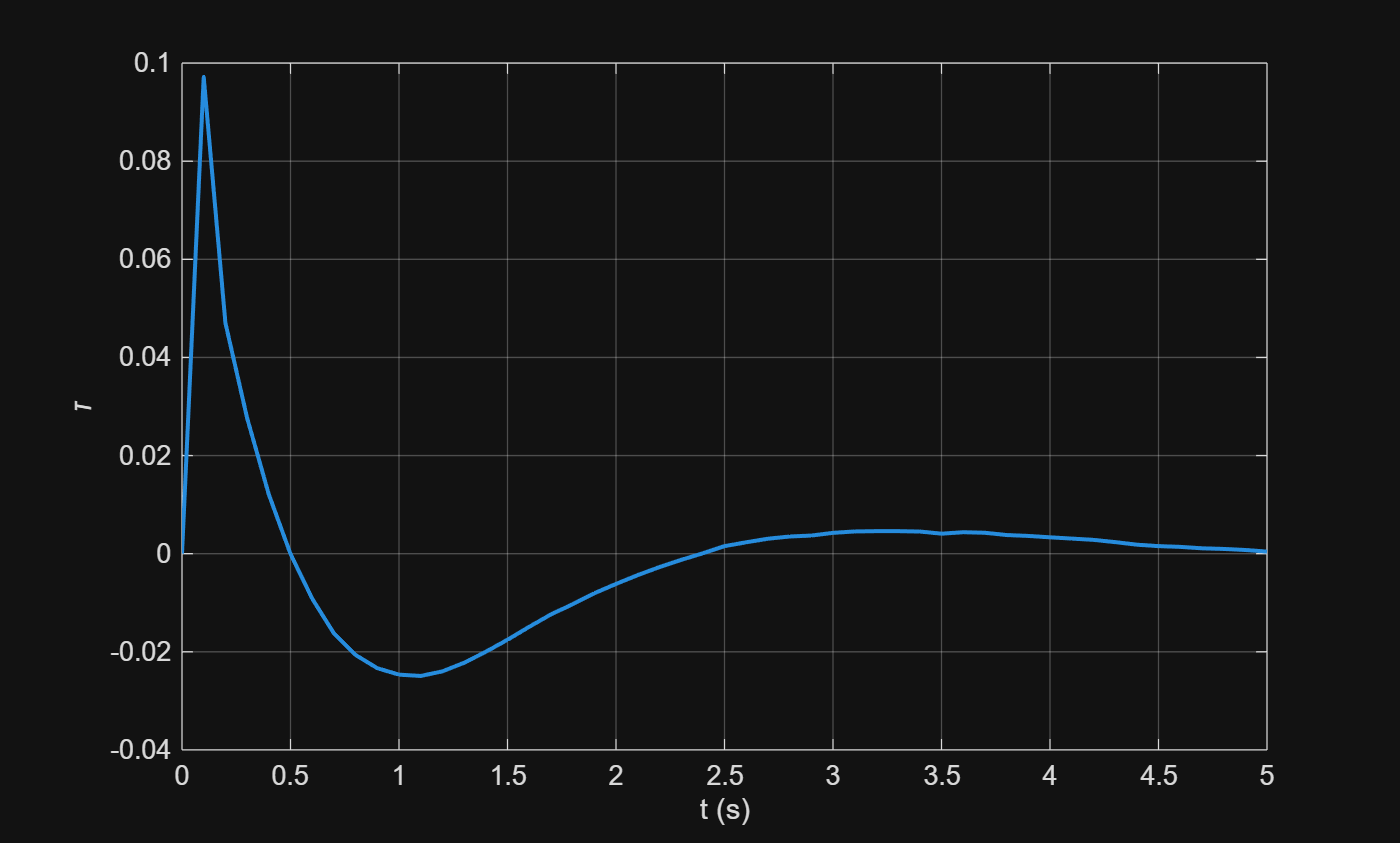


figure(3)
plot(T, Ud, 'LineWidth', 1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;


% Conclusion:
% The difference between the linear and the nonlinear model is affected by
% both nonlinearities and the size of the main parameters of the robot. For
% a small balancing robot it turns out the nonlinearities also become small
% the LQR works well on both the linear and nonlinear model. How well the
% Controller works also depends on the relationship between the different
% parameters aswell as the magnitude of the values, but this could be
% because of nonlinearities in the parameters (scaled differently).

% For small angles up to about
% This is because the nonlinear effects are small even when
% The model is well outside the linearized 
